# Tema 5 - Integración Numèrica (V) 

### Matlab - Trapezis

Consulta la documentació i exemples de [trapz](https://es.mathworks.com/help/matlab/ref/trapz.html) i l'exemple de [integració de dades numèriques](https://es.mathworks.com/help/matlab/math/integration-of-numeric-data.html)

### Matlab - Romberg

Podeu fer ús dels codis de Matlab File Exchange, [codis](https://es.mathworks.com/matlabcentral/fileexchange/58286-romberg) 

### Matlab - Integració adaptativa

% fplot(@(x)humps(x),[0,1]),title('funció humps')
% valor = integral(@(x)humps(x),0,1,'RelTol',1e-8,'AbsTol',1e-13);
% fprintf('integral_valor numèric = %0.12f\t',valor);
% quadgui(@(x)humps(x),0,1,1.0e-3)

## Fórmules d'integració GAUSSIANA

Podeu descarregar els codis de MatLab File Exchange:   

- [Gaussian quadratures for several orthogonal polynomials](https://es.mathworks.com/matlabcentral/fileexchange/48144-gaussian-quadratures-for-several-orthogonal-polynomials) (Chebyshev)

- [Legendre Laguerre and Hermite - Gauss Quadrature](https://es.mathworks.com/matlabcentral/fileexchange/26737-legendre-laguerre-and-hermite-gauss-quadrature?s_tid=prof_contriblnk)

## Polinomis de Legendre

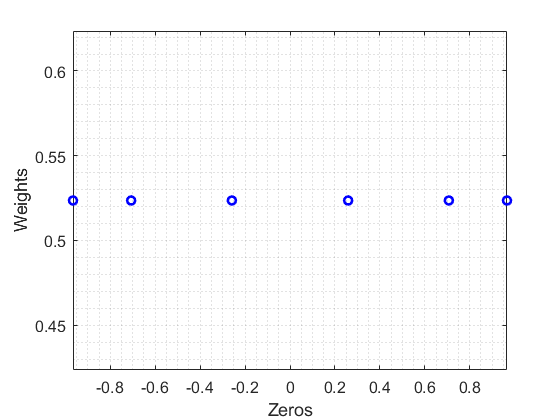

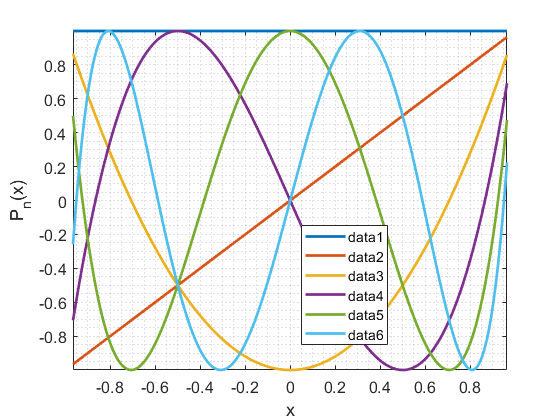

xi =    -0.9659
   -0.7071
   -0.2588
    0.2588
    0.7071
    0.9659


w =     0.5236
    0.5236
    0.5236
    0.5236
    0.5236
    0.5236


clc,clf,clearvars
m = 6;

[xi,w] = gauss_quad(m,'cheby')    % Felipe Uribe, Gaussian quadratures for several orthogonal polynomials 

x2 =    -0.9325
   -0.6612
   -0.2386
    0.2386
    0.6612
    0.9325


w2 =     0.1713
    0.3608
    0.4679
    0.4679
    0.3608
    0.1713


[x2, w2] = GaussLegendre(m)    % Geert Van Damme, Legendre Laguerre and Hermite - Gauss Quadrature

## Polinomis de Chebyshev

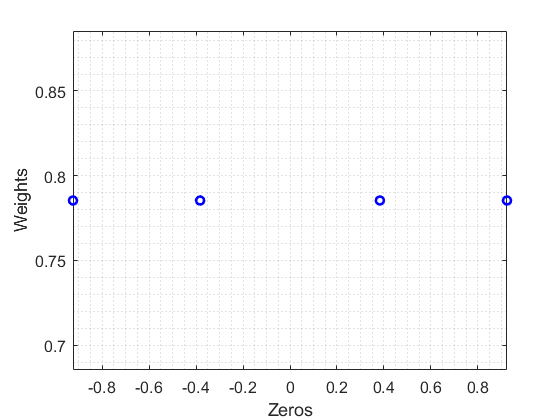

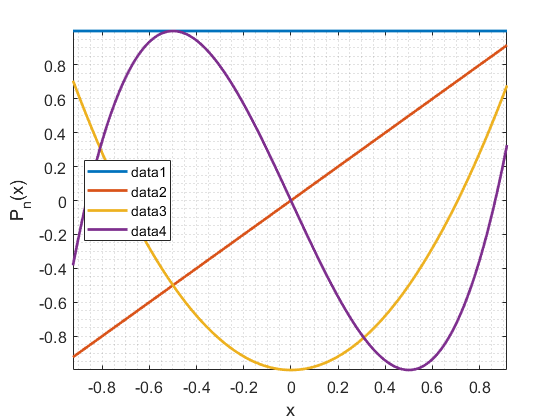

xi =    -0.9239
   -0.3827
    0.3827
    0.9239


w =     0.7854
    0.7854
    0.7854
    0.7854


clc,clf,clearvars
m = 4;

[xi,w] = gauss_quad(m,'cheby')

# Exemple de teoria

### 
$$\displaystyle \int_{-1}^1 e^\frac{-x^2}{2} dx\ \approx\  { 1.71124878378430\pm 0.510^{-14}}$$
 

Ie = integral(@(x)exp(-x.^2/2),-1,1);   % valor exacte

integral valor numèric exacte = 1.71124878378430	

fprintf('integral valor numèric exacte = %0.14f\t',Ie);
format long g
% Gauss Legendre 
f = @(x)exp(-x.^2/2);
a = -1; b = 1;
%%

m =      2


m=2
[x, w] = GaussLegendre(m);

GL2 =           1.69296344978123


GL2=sum(w.*f(x))

Gerror =           0.01828533400307


Gerror=abs(GL2-Ie)
%%

m =      3


m=3
[x, w] = GaussLegendre(m);

GL2 =           1.71202024520191


GL2=sum(w.*f(x))

Gerror =       0.000771461417610864


Gerror=abs(GL2-Ie)

%%

m =      4


m=4
[x, w] = GaussLegendre(m);

GL2 =           1.71122450459949


GL2=sum(w.*f(x))

Gerror =       2.42791848077406e-05


Gerror=abs(GL2-Ie)


# Exemple canvi d'interval

## 
$$  I=\displaystyle\int_{1}^{2} \ln(x)\,dx = \frac{1}{2}\int_{-1}^{1} \ln\Big(\frac{t+3}{2}\Big)\,dt \,.$$


f = @(x)log(x);
a = 1; b = 2;
Ie = integral(f,a,b);   % valor exacte

integral valor numèric exacte = 0.38629436111989	

fprintf('integral valor numèric exacte = %0.14f\t',Ie);
%%

m =      4


m=4

x =         -0.861136311594053
        -0.339981043584856
         0.339981043584856
         0.861136311594053


w =          0.347854845137454
         0.652145154862546
         0.652145154862546
         0.347854845137454


[x, w] = GaussLegendre(m)

GL4 =          0.386294496938714


GL4=0.5*sum(w.*f((x+3)/2))

Gerror =       1.35818823410183e-07


Gerror=abs(GL4-Ie)

# Exemple Chebyshev

## 
$$$\quad\displaystyle  \int_{-1}^{1}\frac{|x|}{\sqrt{1-x^2}}dx $$$


clc; clear variables; format compact;
format short g;
a=-1;b=1;
g=@(x)abs(x);

m =      6

Gauss Txebixev 

m = 6

[x, w] = gauss_quad(m,'cheby');

GL2 =         2.023

GL2 = sum(w.*g(x))

Error

f=@(x)(abs(x)./sqrt(1-x.^2));
a = -1; b = 1;
Ie = integral(f,a,b);   % valor exacte

integral valor numèric exacte = 1.99999999999993	

fprintf('integral valor numèric exacte = %0.14f\t',Ie);

E =       0.02303

E = abs(Ie-GL2)

# EXERCICI 1 (pàgina 20)

## 
$$$ \rm{a)}\quad\displaystyle\int_{-1}^{1}e^xdx $$$


Valor exacte

clearvars,format short g;
a=-1;b=1;
R1 = exp(b)-exp(a)
fun=@(x)exp(x);

Gauss Legendre m=2

Error

## 
$$$\rm{b)}\quad\displaystyle \int_{0}^{1}(7+14x^6)dx $$$


Valor exacte

clear variables; 
a=0;b=1;
fun=@(x)(7+14.*x.^6);
R1 = integral(fun,a,b)

Gauss Legendre m=2

Error

## 
$$$\rm{c)}\quad\displaystyle \int_{0}^{3}x^2e^{x} dx $$$


Valor exacte

clear variables; 
a=0;b=3;
fun=@(x)(x.^2).*exp(x);
R1 = integral(fun,a,b);

Gauss Legendre m=2

Error

# EXERCICI 2 (pàgina 21)

## 
$$$\rm{a)}\quad\displaystyle \int_{-1}^{1}cos(x) dx $$$


Valor exacte

clear variables; 
a=-1;b=1;
fun=@(x)cos(x);
R1 = integral(fun,a,b);

Gauss Legendre m=4

Errors

## 
$$$\rm{b)}\quad\displaystyle \int_{-1}^{1}e^xdx $$$


Valor exacte

clc; clear variables; format compact;
format short g;
a=-1;b=1;
R1 = exp(b)-exp(a)
fun=@(x)exp(x);

Gauss Legendre m=4

Error

## 
$$$\rm{c)}\quad\displaystyle \int_{0}^{1}\ln(x)sin^2(x)dx $$$


Valor exacte

Gauss Legendre m=7

Error

## 
$$$\rm{d)}\quad\displaystyle \int_{0}^{1}\ln(1+\cos(x))dx $$$


Valor exacte

clear variables; 
a=0;b=1;
fun=@(x)log(1+cos(x));
R1 = integral(fun,a,b);

Gauss Legendre m=4

Error

# EXERCICI 3 (pàgina 22)

## 
$$$\rm{a)}\quad\displaystyle  \int_{-1}^{1}\frac{x^2}{\sqrt{1-x^2}}dx $$$


clc; clear variables; format compact;
format short g;
a=-1;b=1;
fun=@(x)(x.^2);

Gauss Txebixev 

## 
$$$\rm{b)}\quad\displaystyle  \int_{-1}^{1}\frac{\cos(\pi x)}{\sqrt{1-x^2}}dx $$$


clc; clear variables; format compact;
format short g;
a=-1;b=1;
fun=@(x)(cos(pi.*x));

Gauss Txebixev 

## 
$$$\rm{c)}\quad\displaystyle  \int_{0}^{1}\frac{x^2}{\sqrt{x(1-x)}}dx $$$


clc; clear variables; format compact;
format short g;
a=0;b=1;
fun=@(x)(1+x).^2./4;

Gauss Txebixev 

by  M. Àngela Grau Gotés (maig 2020)